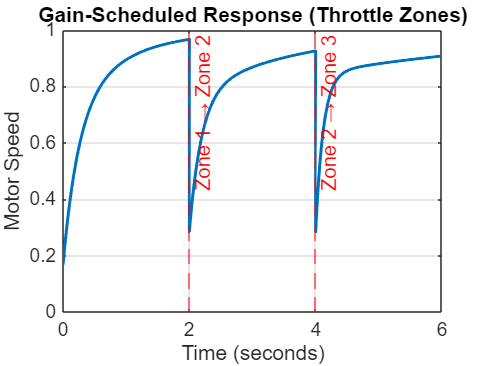

% gain_scheduled.m
% Gain-scheduled PID controller simulation

clc;
clear;
close all;

% === PLANT ===
K = 1;
tau = 0.5;
G = tf(K, [tau 1]);

% === DEFINE PID GAINS FOR 3 ZONES ===
% Zone 1: Low throttle (smooth response)
C1 = pid(2, 2.5, 0.1);

% Zone 2: Mid throttle (balanced)
C2 = pid(3, 2, 0.2);

% Zone 3: High throttle (fast response)
C3 = pid(5, 1.5, 0.2);

% Closed-loop systems
T1 = feedback(C1 * G, 1);
T2 = feedback(C2 * G, 1);
T3 = feedback(C3 * G, 1);

% === TIME SEGMENTS ===
t1 = 0:0.01:2;   % Zone 1
t2 = 0:0.01:2;   % Zone 2
t3 = 0:0.01:2;   % Zone 3

% Simulate responses
y1 = step(T1, t1);
y2 = step(T2, t2);
y3 = step(T3, t3);

% Combine time and outputs
t = [t1, t2+2, t3+4];
y = [y1; y2; y3];

% === PLOT ===
figure;
plot(t, y, 'LineWidth', 1.5);
grid on;
title('Gain-Scheduled Response (Throttle Zones)');
xlabel('Time (seconds)');
ylabel('Motor Speed');

% Mark zone transitions
xline(2, '--r', 'Zone 1 → Zone 2');
xline(4, '--r', 'Zone 2 → Zone 3');

% === SAVE PATH ===
save_path = 'C:\Users\SABEE\OneDrive\Desktop\Attachments\Desktop\sabeeh\My projects\Control systems\end_eval';

if ~exist(save_path, 'dir')
    mkdir(save_path);
end

saveas(gcf, fullfile(save_path, 'gainscheduled_response.png'));